# Prácticas de Control por Computador (3º GIERM, UMA)

## Práctica 1: Descripción de sistemas discretos en Matlab

#### **Tarea 1**

Escribir la expresión de la función de transferencia discreta (función de transferencia de pulsos) $G\left(z\right)=\frac{z^2 +z+1}{z^3 +3z^2 +5z+1}$ utilizando los comandos **tf** y `zpk` especificando un tiempo de muestreo de $T=0\ldotp 1$ (usar este mismo tiempo de muestreo en el resto de tareas).

% Tu código aquí
T=0.1; 
G=tf([1 1 1],[1 3 5 1],T)

G =
 
       z^2 + z + 1
  ---------------------
  z^3 + 3 z^2 + 5 z + 1
 
Sample time: 0.1 seconds
Discrete-time transfer function.



G=zpk(zero(G),pole(G),1,T)

G =
 
            (z^2 + z + 1)
  ---------------------------------
  (z+0.2291) (z^2 + 2.771z + 4.365)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.



#### **Tarea 2**

Hallar la función de transferencia del conjunto en paralelo y expresarla.

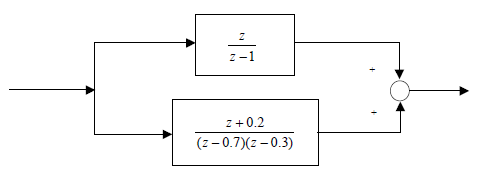

% Tu código aquí
z=tf('z',T);
G=z/(z-1);
H=(z+0.2)/((z-0.7)*(z-0.3));
Gz=zpk(G+H)

Gz =
 
  (z-0.9011) (z^2 + 0.9011z + 0.222)
  ----------------------------------
        (z-1) (z-0.7) (z-0.3)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.



Gz=zpk(parallel(G,H))

Gz =
 
  (z-0.9011) (z^2 + 0.9011z + 0.222)
  ----------------------------------
        (z-1) (z-0.7) (z-0.3)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.



Resultado esperado:

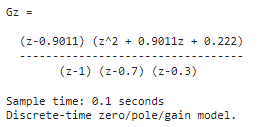

#### **Tarea 3**

Hallar la función de transferencia reducida del conjunto de bloques de la imagen, que posee realimentación negativa:

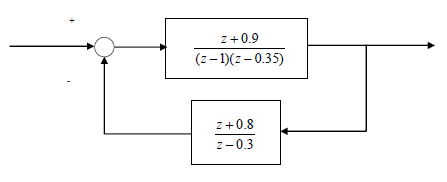

% Tu código aquí
G=zpk(-0.9,[1 0.35],1,T);
H=zpk(-0.8,0.3,1,T);
Gz=feedback(G,H)

Gz =
 
           (z+0.9) (z-0.3)
  ----------------------------------
  (z+0.2313) (z^2 - 0.8813z + 2.659)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.



Gz=minreal(G*(1+H*G))

Gz =
 
  (z+0.9) (z+0.2313) (z^2 - 0.8813z + 2.659)
  ------------------------------------------
          (z-1)^2 (z-0.35)^2 (z-0.3)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.



`Resultado esperado:`

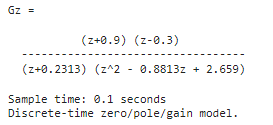

#### **Tarea 4**

Para la función de transferencia $G\left(z\right)=\frac{z^2 +0\ldotp 3z}{z^3 +z^2 +z+0\ldotp 1}$ hallar las raíces de la ecuación característica y obtener la descomposición en fracciones simples a través del comando `residue`.

% Tu código aquí
G=(z^2+0.3*z)/(z^3+z^2+z+0.1)

G =
 
      z^2 + 0.3 z
  -------------------
  z^3 + z^2 + z + 0.1
 
Sample time: 0.1 seconds
Discrete-time transfer function.



[zeros,poles,k]=tfdata(G);
poles=cell2mat(poles)

poles =   -0.4445 + 0.8389i
  -0.4445 - 0.8389i
  -0.1109 + 0.0000i


[r,p,k]=residue(G.num{1},G.den{1})

r =    0.5129 + 0.1471i
   0.5129 - 0.1471i
  -0.0257 + 0.0000i


p =   -0.4445 + 0.8389i
  -0.4445 - 0.8389i
  -0.1109 + 0.0000i



k =

     []



`Resultado esperado:`

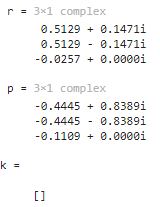

#### **Tarea 5**

Hallar la respuesta temporal ante escalón unitario del sistema con un cero en $z_{{\;}_0 } =-0\ldotp 9$, dos polos situados en $z_{\textrm{p1}} =1$ y $z_{\textrm{p2}} =0\ldotp 8$ y ganancia $0\ldotp 05$ en bucle cerrado y realimentación unitaria. 

% Tu código aquí
G=tf(zpk(-0.9,[1 0.8],0.05,T))

G =
 
   0.05 z + 0.045
  -----------------
  z^2 - 1.8 z + 0.8
 
Sample time: 0.1 seconds
Discrete-time transfer function.



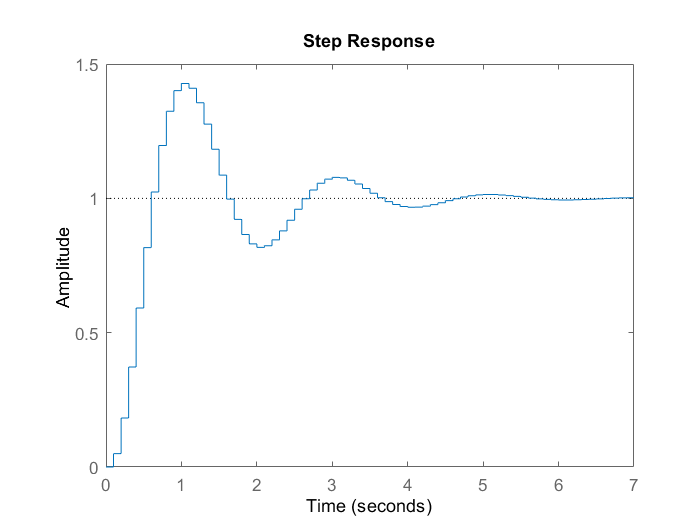

Gz=feedback(G,1);
step(Gz)

`Resultado esperado:`

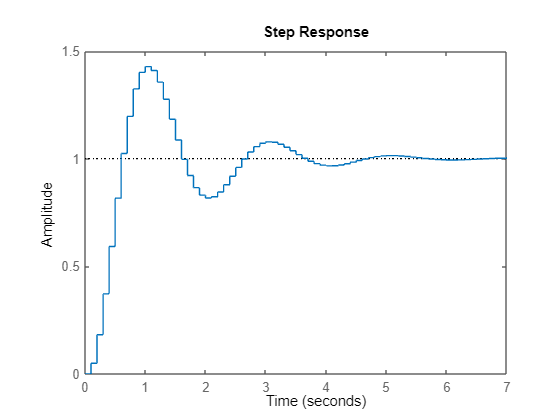

Dibujar el lugar de las raíces usando además el comando `zgrid`.

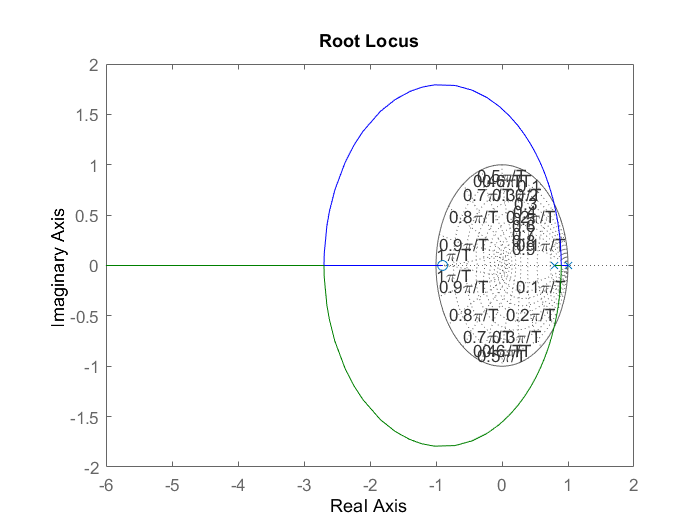

% Tu código aquí
rlocus(G)
zgrid

`Resultado esperado:`

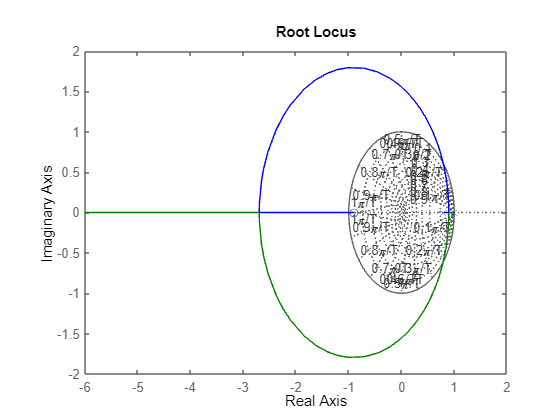

#### **Tarea 6**

Simular las respuesta del sistema $G\left(z\right)=\frac{z}{z^2 -1\ldotp 7z+0\ldotp 7}$ en bucle cerrado y con realimentación unitaria ante entradas impulso, escalón y rampa durante 3 segundos, graficándolas en la misma figura con `subplot`. Utilizando el comando de representación de señales discretas `stem `para mostrar las respuestas del sistema.

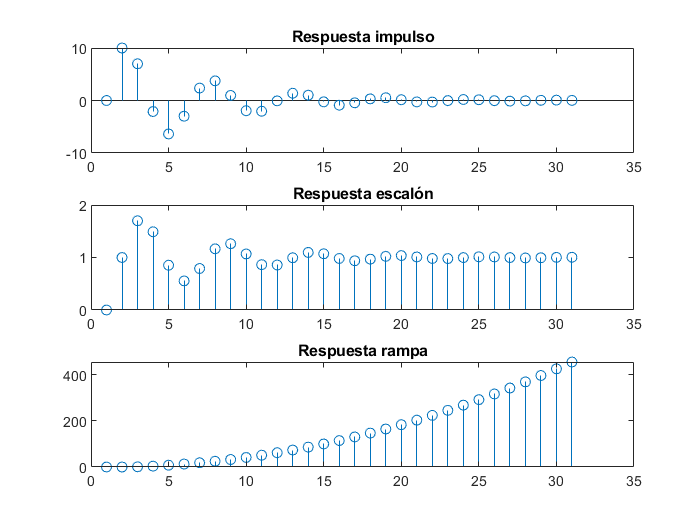

z=tf('z',T);
G=z/(z^2-1.7*z+0.7);
Gz=feedback(G,1);
figure 
subplot(3,1,1)
stem(impulse(Gz,3))
title('Respuesta impulso')
subplot(3,1,2)
stem(step(Gz,3))
title('Respuesta escalón')
subplot(3,1,3)
stem(step(Gz*z/(z-1)^2,3))
title('Respuesta rampa')

% u= 0:T:3
% t= 0:T:3
% lsim(Gz,u,t)

`Resultado esperado:`